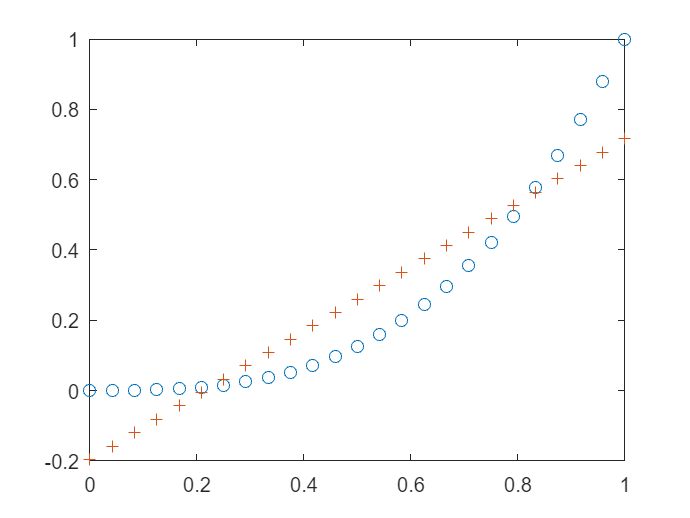

t = linspace(0,1,25); % Der Strichpunkt am Ende der Zeile verhindert die Ausgabe der Werte, sie werden nur gespeichert.
fun = t.^3; %Punktweise quadrieren weil "t" ein Vektor ist. Die Fkt "fun" ist eine Funktion dritter Ordnung
hold off

plot(t,fun,"o")
coefs = polyfit(t,fun, 2)% Der 1er am Ende gibt den Grad der Näherungsfunktion

coefs =     1.5000   -0.5878    0.0439


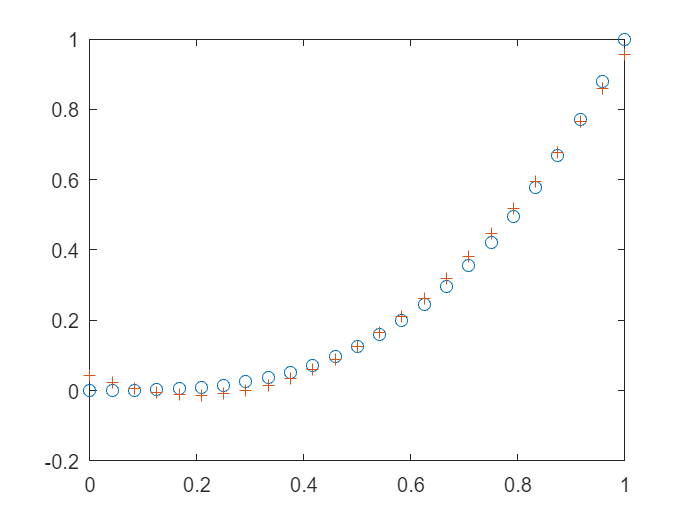

hold on

fun_fit = polyval(coefs,t);
plot(t, fun_fit, '+')

delta = fun-fun_fit;
dot(delta, delta) %Summe der Abstandsquadrate (siehe Folie)

ans = 0.0112